folder = "Round2\"

folder = "Round2\"

folder_doc = "Doc\"

folder_doc = "Doc\"


filenameLRs = folder+"LRs.csv"

filenameLRs = "Round2\LRs.csv"

filenameLRp = folder+"LRp.csv"

filenameLRp = "Round2\LRp.csv"

filenameCRs = folder+"CRs1.csv"

filenameCRs = "Round2\CRs1.csv"

filenameCRp = folder+"CRp.csv"

filenameCRp = "Round2\CRp.csv"

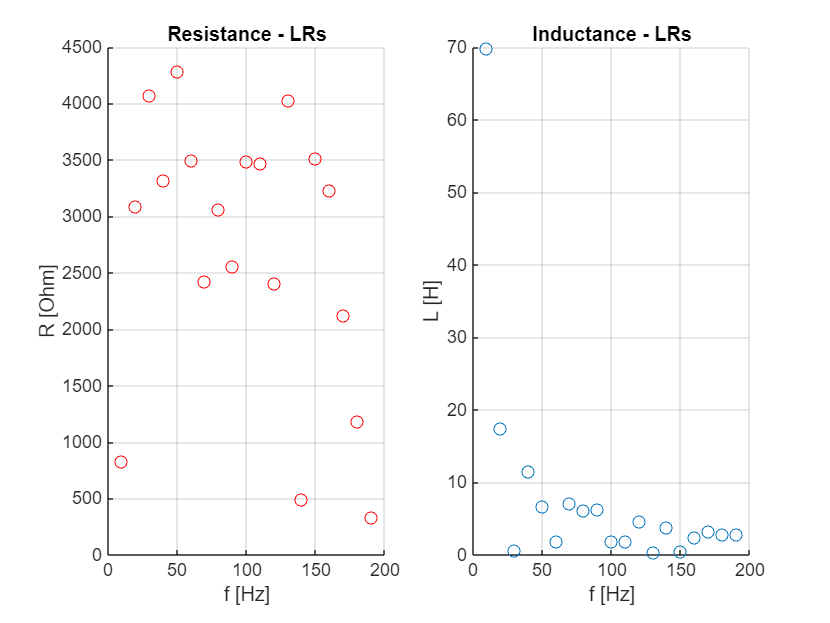


Rn = 1000;

% LR series
% Measured complex plotting
T = readmatrix(filenameLRs);
FFT_BUFFER_SIZE = 1024;
f = T(:,1);
Z_c = T(:,2)+1i*T(:,3);
Z_a = T(:,4);
Z_c = Z_c*Rn;
Z_a = Z_a*Rn;
Z_c_a = abs(Z_c)*2/FFT_BUFFER_SIZE;
Z_fi = angle(Z_c);

figure()
% subplot(1,3,1)
% scatter(f,Z_c_a);
% hold on
% scatter(f,Z_a);
% hold off
% title('Z at peak indeces - LRs')
% legend('|Z| from comp','|Z| from abs')
% grid on

R_LRs = abs(real(Z_c));
L_LRs = abs(imag(Z_c))./(2*pi*f);

subplot(1,2,1)
scatter(f,R_LRs,'red')
title("Resistance - LRs")
xlabel("f [Hz]")
ylabel("R [Ohm]")
%ylim([0 4])
grid on

subplot(1,2,2)
scatter(f,L_LRs)
title("Inductance - LRs")
xlabel("f [Hz]")
ylabel("L [H]")
%ylim([0 0.008])
grid on

fig = gcf;
print_figures(fig,folder_doc+"LRs_plot",3000,1500,300);

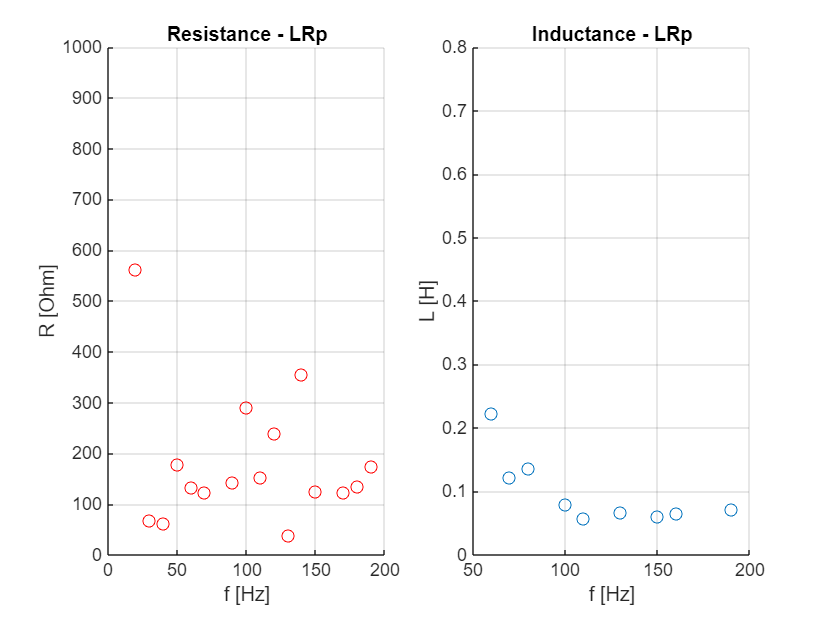



% LR parallel
% Measured complex plotting
T = readmatrix(filenameLRp);
FFT_BUFFER_SIZE = 1024;
f = T(:,1);
Z_c = T(:,2)+1i*T(:,3);
Z_a = T(:,4);
Z_c = Z_c*Rn;
Z_a = Z_a*Rn;
Z_c_a = abs(Z_c)*2/FFT_BUFFER_SIZE;
Z_fi = angle(Z_c)+pi/2;

figure()
% subplot(1,3,1)
% scatter(f,Z_c_a);
% hold on
% scatter(f,Z_a);
% hold off
% title('Z at peak indeces - LRp')
% legend('|Z| from comp','|Z| from abs')
% grid on

R_LRp = Z_a.*sqrt(1+tan(Z_fi).^2);
L_LRp = Z_a./(2*pi*f).*sqrt(1+tan(Z_fi).^2)./tan(Z_fi);

subplot(1,2,1)
scatter(f,R_LRp,'red')
title("Resistance - LRp")
xlabel("f [Hz]")
ylabel("R [Ohm]")
ylim([0 1000])
grid on

subplot(1,2,2)
scatter(f,L_LRp)
title("Inductance - LRp")
xlabel("f [Hz]")
ylabel("L [H]")
ylim([0 0.8])
grid on

fig = gcf;
print_figures(fig,folder_doc+"LRp_plot",3000,1500,300);

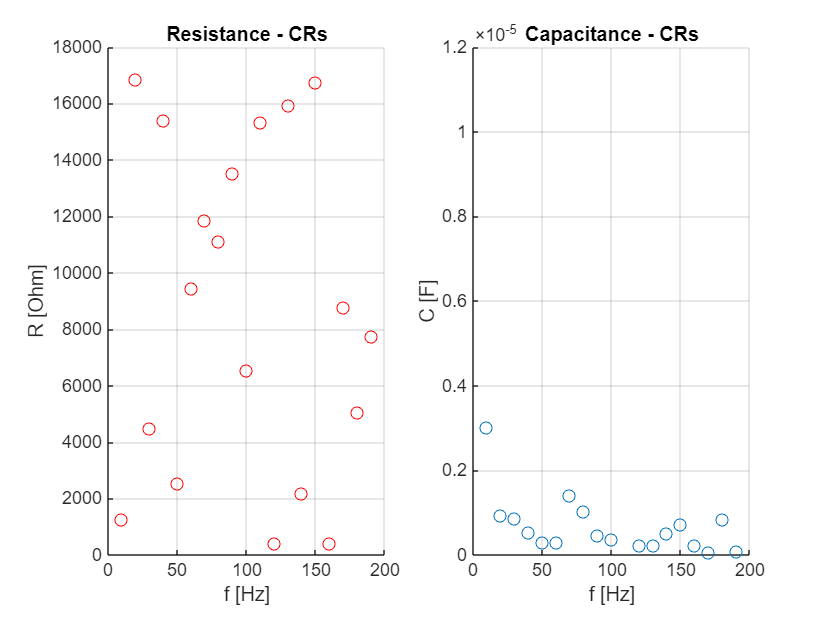



% CR series
% Measured complex plotting
T = readmatrix(filenameCRs);
FFT_BUFFER_SIZE = 1024;
f = T(:,1);
Z_c = T(:,2)+1i*T(:,3);
Z_a = T(:,4);
Z_c = Z_c*Rn;
Z_a = Z_a*Rn;
Z_c_a = abs(Z_c)*2/FFT_BUFFER_SIZE;
Z_fi = angle(Z_c);

figure()
% subplot(1,3,1)
% scatter(f,Z_c_a);
% hold on
% scatter(f,Z_a);
% hold off
% title('Z at peak indeces - CRs')
% legend('|Z| from comp','|Z| from abs')
% grid on

R_CRs = abs(real(Z_c));
C_CRs = 1./abs(imag(Z_c))./(2*pi*f);

subplot(1,2,1)
scatter(f,R_CRs,'red')
title("Resistance - CRs")
xlabel("f [Hz]")
ylabel("R [Ohm]")
%ylim([0 20])
grid on

subplot(1,2,2)
scatter(f,C_CRs)
title("Capacitance - CRs")
xlabel("f [Hz]")
ylabel("C [F]")
ylim([0 0.000012])
grid on

fig = gcf;
print_figures(fig,folder_doc+"CRs_plot",3000,1500,300);

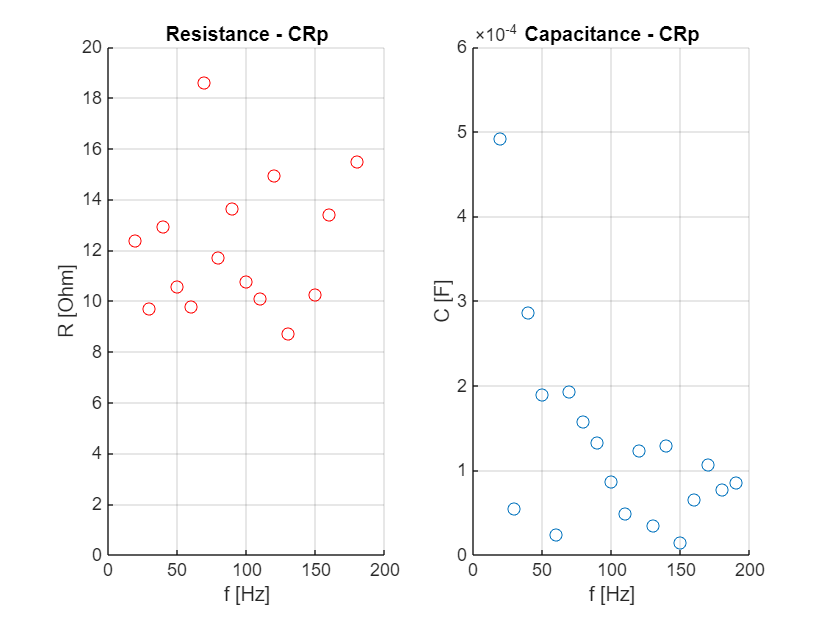


% CR parallel
% Measured complex plotting
T = readmatrix(filenameCRp);
FFT_BUFFER_SIZE = 1024;
f = T(:,1);
Z_c = T(:,2)+1i*T(:,3);
Z_a = T(:,4);
Z_c = Z_c*Rn;
Z_a = Z_a*Rn;
Z_c_a = abs(Z_c)*2/FFT_BUFFER_SIZE;
Z_fi = angle(Z_c);

figure()
% subplot(1,3,1)
% scatter(f,Z_c_a);
% hold on
% scatter(f,Z_a);
% hold off
% title('Z at peak indeces - CRp')
% legend('|Z| from comp','|Z| from abs')
% grid on

R_CRp = Z_a.*sqrt(1+tan(Z_fi).^2);
C_CRp = abs(1./Z_a./(2*pi*f).*tan(Z_fi)./sqrt(1+tan(Z_fi).^2));

subplot(1,2,1)
scatter(f,R_CRp,'red')
title("Resistance - CRp")
xlabel("f [Hz]")
ylabel("R [Ohm]")
ylim([0 20])
grid on

subplot(1,2,2)
scatter(f,C_CRp)
title("Capacitance - CRp")
xlabel("f [Hz]")
ylabel("C [F]")
ylim([0 0.0006])
grid on

fig = gcf;
print_figures(fig,folder_doc+"CRp_plot",3000,1500,300);